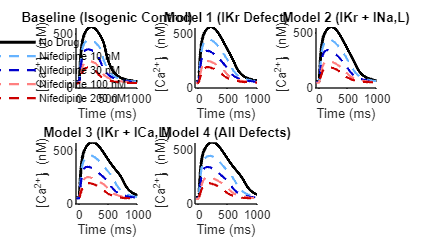

Processing Baseline (Isogenic Control)...
Processing Model 1 (IKr Defect)...
Processing Model 2 (IKr + INa,L)...
Processing Model 3 (IKr + ICa,L)...
Processing Model 4 (All Defects)...


% Script: Drug_Challenge_Calcium_Overlays.m
% Generates Calcium Transient morphology overlays for 5 Models across 4 Drug Conditions
close all; clear; clc;

% Load initial conditions and the original baseline parameters
load ICs_baseline;
load baseline_parameter_inputs;

% Store a clean copy of the baseline parameters
original_baseline_params = baseline_parameter_inputs;

% ========================================================================
%  START: EXPERIMENTAL CONFIGURATION 
% ========================================================================

num_models = 5;
model_names = {'Baseline (Isogenic Control)', 'Model 1 (IKr Defect)', ...
               'Model 2 (IKr + INa,L)', 'Model 3 (IKr + ICa,L)', ...
               'Model 4 (All Defects)'};

% drug_type: 0 = No Drug, 1 = Mexiletine, 2 = Nifedipine
drug_types = [0, 2, 2, 2, 2]; 
drug_doses = [0, 10, 30 100, 200]; % uM for Mex, nM for Nif
drug_labels = {'No Drug', 'Nifedipine 10 nM', ...
               'Nifedipine 30 nM', 'Nifedipine 100 nM', 'Nifedipine 200 nM'};

% Colors for traces
trace_colors = [0 0 0; 0.4 0.7 1; 0 0 0.8; 1 0.5 0.5; 0.8 0 0];

% Setup Figure
figure('Name', 'Drug Challenge Calcium Overlays', 'Color', 'w', 'Position', [100, 100, 1400, 800]);

% ========================================================================
%  START: BATCH SIMULATION BLOCK
% ========================================================================

for model_id = 0:(num_models - 1)
    
    fprintf('Processing %s...\n', model_names{model_id + 1});
    
    subplot(2, 3, model_id + 1);
    hold on;
    
    for cond = 1:length(drug_types)
        
        current_drug = drug_types(cond);
        current_dose = drug_doses(cond);
        
        % --- 1. Reset parameters ---
        modified_params = original_baseline_params;
        modified_params(83) = 1; % Pacing ON
        
        baseline_C_persist_CaL = modified_params(86);
        baseline_C_persist_NaL = modified_params(87);
        
        modified_params(1) = modified_params(1) * 5;     % g_K1
        modified_params(7) = modified_params(7) * 1.45;  % g_Na
        
        % --- 2. Apply Disease Model Modifications ---
        if model_id == 1
            modified_params(2) = modified_params(2) * (1 - 0.725);
        elseif model_id == 2
            modified_params(2) = modified_params(2) * (1 - 0.725);
            modified_params(87) = baseline_C_persist_NaL * 2.31 * 3; 
        elseif model_id == 3
            modified_params(2) = modified_params(2) * (1 - 0.725);
            modified_params(86) = baseline_C_persist_CaL * 2.29; 
        elseif model_id == 4
            modified_params(2) = modified_params(2) * (1 - 0.725);
            modified_params(87) = baseline_C_persist_NaL * 2.31 * 3;
            modified_params(86) = baseline_C_persist_CaL * 2.29;
        end
        
        % --- 3. Apply Drug Block ---
        if current_drug == 1 % MEXILETINE
            fract_cond_INa_peak = 1 / (1 + (current_dose / 40));
            fract_cond_INa_late = 1 / (1 + (current_dose / 10));
            
            modified_params(7) = modified_params(7) * fract_cond_INa_peak;
            modified_params(87) = modified_params(87) * fract_cond_INa_late;
            
        elseif current_drug == 2 % NIFEDIPINE
            fract_cond_ICaL = 1 / (1 + (current_dose / 15));
            modified_params(5) = modified_params(5) * fract_cond_ICaL;
        end
        
        % --- 4. Run ODE Simulation ---
        options = odeset('MaxStep',1,'InitialStep',2e-2);
        run_time = 30e3; 
        [Time, values] = ode15s(@ipsc_function,[0, run_time], Y_init, options, modified_params);
        
        % --- 5. Extract Vm (for alignment) and Cai (for plotting) ---
        Vm = values(:,1);
        Cai = values(:,3);
        
        inds_time_start = find(Time > 8000, 1, 'first'); %original 0
        inds_time_end   = find(Time > 13000, 1, 'first');%original 5000
        
        beat_time_raw = Time(inds_time_start:inds_time_end);
        beat_vm_raw   = Vm(inds_time_start:inds_time_end);
        beat_cai_raw  = Cai(inds_time_start:inds_time_end);
        
        % Find AP upstroke to align BOTH voltage and calcium transients
        results = calculate_ap_stats(beat_time_raw, beat_vm_raw);
        aligned_time = beat_time_raw - results.t_depol;
        
        % Convert Cai from mM to nM
        beat_cai_nM = beat_cai_raw * 1e6;
        
        % --- 6. Plot Trace ---
        if current_drug == 0
            line_style = '-';
            line_width = 2.0;
        else
            line_style = '--';
            line_width = 1.5;
        end
        
        plot(aligned_time, beat_cai_nM, 'Color', trace_colors(cond,:), ...
            'LineStyle', line_style, 'LineWidth', line_width);
        
    end
    
    % Format Subplot
    title(model_names{model_id + 1});
    xlabel('Time (ms)');
    ylabel('[Ca^{2+}]_i (nM)');
    xlim([-50 1000]); 
    % Removed ylim to let MATLAB auto-scale the Ca peaks naturally
    set(gca, 'box', 'off', 'tickdir', 'out');
    
    if model_id == 0
        legend(drug_labels, 'Location', 'northeast');
        legend boxoff;
    end
    
    hold off;
end


% ========================================================================
%  HELPER FUNCTION: Used solely to find t_depol for alignment
% ========================================================================

function results = calculate_ap_stats(time, voltage)
    dV = diff(voltage);
    dt = diff(time);
    dVdt = dV ./ dt; 
    
    [~, idx_max_diff] = max(dVdt);
    results.t_depol = time(idx_max_diff);
end